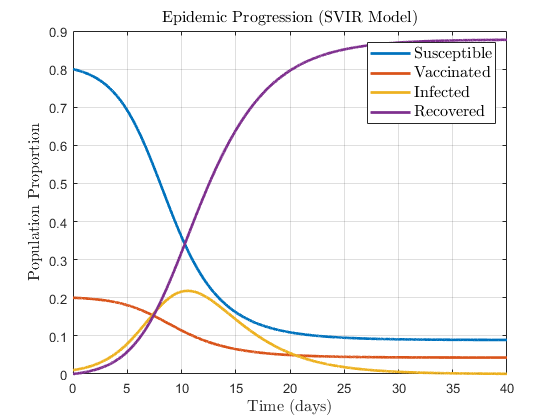

clear; clc; close all;

%% System Parameters
beta = 2.5 * (1/3);         % Infection rate [1/(person*day)]
eta = 0.30;                 % Vaccination efficacy [dimensionless]
gamma = 1/3;                % Recovery rate [1/day]

x = 0.2;                    % Proportion of vaccinated individuals initially
S0 = 1-x;                   % Initial proportion of susceptible people
V0 = x;                     % Initial proportion of vaccinated people
I0 = 0.01;                     % Initial proportion of infected people
R0 = 0;                     % Initial proportion of recovered people

t = 0:0.01:40;              % Simulation time vector [days]

%% Calling and Plotting Model
[S, V, I, R] = epidemic(beta, eta, gamma, S0, V0, I0, R0, t);

figure
plot(t, S, 'linewidth', 2)
hold on; grid on
plot(t, V, 'linewidth', 2)
plot(t, I, 'linewidth', 2)
plot(t, R, 'linewidth', 2)

title('Epidemic Progression (SVIR Model)', 'fontsize', 12, 'Interpreter', 'latex')
xlabel('Time (days)', 'fontsize', 12, 'Interpreter', 'latex')
ylabel('Population Proportion', 'fontsize', 12, 'Interpreter', 'latex')
legend('Susceptible', 'Vaccinated', 'Infected', 'Recovered', 'fontsize', 12, 'Interpreter', 'latex')

%% Function


function [S, V, I, R] = epidemic(beta, eta, gamma, S0, V0, I0, R0, t) 
% Inputs:   
%   beta:     Infection rate [1/(person*day)] (scalar)
%   eta:      Vaccination efficacy [dimensionless] (scalar)
%   gamma:    Recovery rate [1/day] (scalar)
%   S0:       Initial proportion of susceptible people (scalar)
%   V0:       Initial proportion of vaccinated people (scalar)
%   I0:       Initial proportion of infected people (scalar)
%   R0:       Initial proportion of recovered people (scalar)
%   t:        Interval of integration. Must have at least 3 elements. [day] (vector)
% 
% Outputs:
%   S:        Proportion of susceptible individuals over time (vector)
%   V:        Proportion of vaccinated individuals over time (vector)
%   I:        Proportion of infected individuals over time (vector)
%   R:        Proportion of recovered individuals over time (vector)

% The system of equations is:
%   dS/dt = -beta * S * I
%   dV/dt = -(1-eta) * beta * V * I
%   dI/dt = beta * S * I + (1-eta) * beta * V * I - gamma * I
%   dR/dt = gamma * I
% 
% Define y = [S; V; I; R]

dydt = @(t, y) [(-beta * y(1) * y(3));
                (-(1-eta) * beta * y(2) * y(3));
                (beta * y(1) * y(3) + (1-eta) * beta * y(2) * y(3) - gamma * y(3));
                (gamma * y(3))];

[~, y] = ode45(dydt, t, [S0 V0 I0 R0]);

% Parse outputs
S = y(:, 1);
V = y(:, 2);
I = y(:, 3);
R = y(:, 4);

end


